# P1. Vehicle Longitudinal Dynamics

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 18 September 2026

### Introduction and objectives

This file contains the coursework instructions and code blocks to complete. In this first exercise, define the properties and design parameters of the FSDriverless race car and develop its first longitudinal dynamic model.

This exercise requires the fundamental longitudinal equation of motion developed in Block 2.

After completing this exercise, you should be able to:

- Write and simulate a vehicle's longitudinal equation of motion.

- Close a simple speed-control loop.

- Recognize the simulation structure that will be reused and expanded in subsequent exercises.

Important: this is the first block of the individual project. The file completed here becomes the longitudinal basis of the race-car control simulator used throughout the course. Keep it.

#### What you will implement

A) Longitudinal acceleration (function pasoLongitudinal)

B) The saturated PI control law (function controlLongitudinal)

### Vehicle parameters

Tip: use a struct. MATLAB structures group related information into fields, each of which can store any data type: numbers, text, vectors or other arrays.

p = struct();
p.m = 230; % mass in kg
p.g = 9.81; % gravitational acceleration
p.rho = 1.225; % air density
p.Cd = 1.0; % aerodynamics
p.Af = 1.1; % frontal area
p.fr = 0.022;
p.Fx_trac_max = 2500; % maximum driving force
p.Fx_fren_max = 5000; % maximum braking force
p.theta = 0; %rad

Reminder: maximum driving force depends on tyre adhesion and powertrain power/torque limits. Maximum braking force is also typically adhesion-limited, with the advantage of all-wheel braking rather than rear-wheel drive, allowing use of the full vehicle mass and available aerodynamic load.

### Vehicle model

Define the physics of longitudinal vehicle motion here. This section will later contain the complete vehicle model.

Given vehicle position and applied driving force, calculate vehicle position at the next time step.

% Longitudinal-dynamics integration
z0 = [0;0]; % vehicle state vector [x,v_x]

function z_next = pasoLongitudinal(z, u, p, dt)
    Fx=u;
    v_x=z(2);

    % resistance forces
    Ra = 0.5*p.rho*p.Cd*p.Af*v_x^2; % aerodynamic resistance
    Rr = p.fr*p.m*p.g*cos(p.theta); % rolling resistance
    Rg = p.m*p.g*sin(p.theta); % gravitational resistance

    % acceleration
    ax = (Fx - Ra - sign(v_x)*Rr - Rg)/p.m;
   
    % speed
    vx_next = max(v_x + ax*dt,0); % speed at the next time instant
    x_next = z(1)+v_x*dt;
    z_next = z;
    z_next(1) = x_next;
    z_next(2) = vx_next;
end

### Speed controller

Define the speed controller using the following diagram:

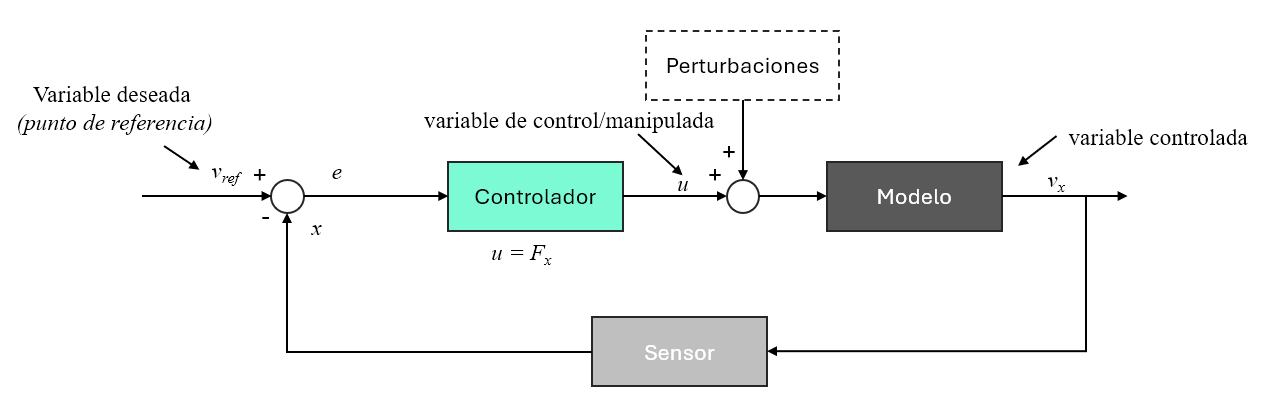

#### Reminder about PI controllers

Implement a PI speed controller so that v_x follows reference v_{ref}. Define the error as$$$$


$$e = v_{ref} - v_x$$


Request driving force proportional to this error plus an integral term that removes steady-state error:


$$F_x = K_p \cdot e + K_i \int{e \cdot dt}$$


Actual force is limited by adhesion and motor capacity. F_x saturates between maximum braking and maximum driving force.$$

**Reminder: controller saturation occurs when its calculated output exceeds the actuator's physical, electrical or software limits.**

Why use driving force as the control variable? It simplifies integration with longitudinal motion by abstracting the powertrain into one variable. A fuller implementation would model accelerator pedal, motor torque and driving force using motor maps, which are nonlinear for combustion engines.

% PI speed controller
ctrl.v_cru = 25; % target cruise speed [m/s]
ctrl.x_fren = 78; % distance at which braking is requested [m]
ctrl.Kp = 800; % proportional gain
ctrl.Ki = 200; % integral gain

function [Fx,e_int] = controlLongitudinal(v_ref, v_x, e_int, dt, ctrl, p)
    e = v_ref - v_x;
    % integral of the error
    e_int = e_int + e*dt;
    Fx = ctrl.Kp*e+ctrl.Ki*e_int;

    % controller saturation limit
    Fx = min(max(Fx,  -p.Fx_fren_max), p.Fx_trac_max);
end

### Test-track geometry

Simulate maximum acceleration for 75 m followed by braking within a box shorter than 25 m, reaching a stop before the 100 m boundary.

p.x_meta = 75;     % timing line [m]
p.x_box  = 100;    % end of braking box [m]

%% ACCELERATION AND BRAKING TEST SIMULATOR [DO NOT MODIFY]
function [hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax)
    N = round(Tmax/dt);
    z = z0;
    hist.t  = zeros(1,N); hist.X  = zeros(1,N); hist.vx = zeros(1,N);
    hist.Fx = zeros(1,N); hist.vr = zeros(1,N);
    e_int = 0;  cruzada = false;  t_evento = NaN;  k_fin = N;
    for k = 1:N
        t = (k-1)*dt;
        if z(1) < ctrl.x_fren,  v_ref = ctrl.v_cru;  else,  v_ref = 0;  end
        [Fx, e_int] = controlLongitudinal(v_ref, z(2), e_int, dt, ctrl, p);
        z = pasoLongitudinal(z, Fx, p, dt);   % input u = [Fx; delta]; delta = 0 in L1
        hist.t(k)=t; hist.X(k)=z(1); hist.vx(k)=z(2); hist.Fx(k)=Fx; hist.vr(k)=v_ref;
        if ~cruzada && z(1) >= p.x_meta,  cruzada = true;  t_evento = t;  end
        if cruzada && z(2) <= 0.05,  k_fin = k;  break;  end
    end
    f = 1:k_fin;
    hist.t=hist.t(f); hist.x=hist.X(f); hist.vx=hist.vx(f);
    hist.Fx=hist.Fx(f); hist.vr=hist.vr(f);
end

### Simulation

dt   = 0.005;
Tmax = 20; 

[hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax);

### Results

**Expected response: the car accelerates from rest to the configured cruise speed (90 km/h), maintains it until the 75 m braking line, then brakes to a stop inside the box, before approximately 100 m.**

fprintf('E1 — crosses %.0f m at t = %.2f s\n', p.x_meta, t_evento);

E1 — cruza 75 m en  t = 3.96 s


fprintf('     stops at X = %.1f m (t = %.2f s)\n', hist.x(end), hist.t(end));

     se detiene en  X = 101.1 m  (t = 14.70 s)


fprintf('     v_max = %.1f m/s = %.0f km/h\n', max(hist.vx), max(hist.vx)*3.6);

     v_max = 30.7 m/s = 111 km/h


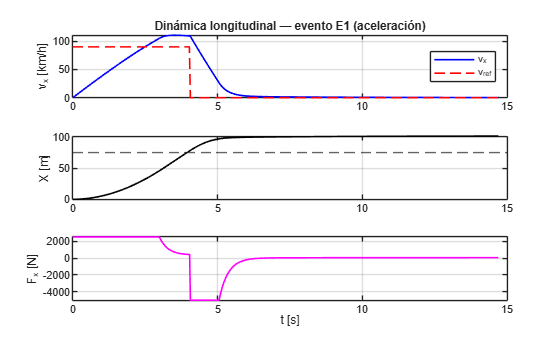

figure('Name','L1 · E1 — results','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vr*3.6,'r--','LineWidth',1.2);
  ylabel('v_x [km/h]'); grid on; legend('v_x','v_{ref}','Location','best');
  title('Longitudinal dynamics — E1 acceleration event');
subplot(3,1,2);
  plot(hist.t, hist.x,'k','LineWidth',1.2); yline(p.x_meta,'--');
  ylabel('X [m]'); grid on;
subplot(3,1,3);
  plot(hist.t, hist.Fx,'m','LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;